Localization Navigation and Smart Mobility

# **Project**

by Martin Molinaro

clc; clear all; close all;


#### **Execution controller**

remove_outliers = true;
show_plots_dataProcessing = false; 
show_plots_AP = false;
show_plots_ML = false;
random_initial_position = false;
NLS = true;
threshold_stopping_criterion = true;
CRB = false; % you must also select NLS (this plotting is computationally demanding)
EKF = true;
show_plots_covarianceEKFM1 = false; %you must also select EKF (may require a lot of time to do it for all the estimations, just do it for visualization)
show_plots_covarianceEKFM3 = false; %you must also select EKF (may require a lot of time to do it for all the estimations, just do it for visualization)
show_plots_comparisonNLSvsEKF = true; % you must also select both NLS and EKF 
show_plots_vel_EKF_M3 = true; % you must also select EKF 
extra_show_pseudo_evolution_in_time = false; % you must also select EKF



#### **Benchmark**

refinement_data_processing = 0.5; % used in outliers removal
NLS_iterations = 50;
NLS_iterative_step = 0.2;
num_samples = 50; % we have to sample the estimated position in order to be computationally able to plot the CRB (may require a few min depending on your sampling choices)
sigma_meas_noise =0.3; % [m] , min accuracy declared on t4f site is 30cm
driving_noise_sigma_pos = 0.005; % [m] : T is 0.1 s [sample rate=10Hz], so sigma_v=0.05 [m/s]
sigma_driving_noise =0.001; %sigma_a=0.001 [m/s^2]
UE_init_COV_pos = 1;
UE_init_COV_vel = 0.1;
speedup = 0.1; % the smaller the faster [real sample rate 10 Hz - 0.1]

** For the accuracy of the measurements I've looked up the manifacturer site for specifications.*

*Source: *[*https://www.tracking4fun.com/*](https://www.tracking4fun.com/)

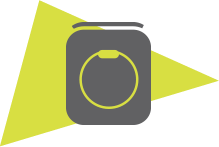

***Tag***

*Transmitting and wearable devices, low consumption and powered by a coin battery. These devices communicate their presence up to 10 times per second to the receivers, which determine their position with an ****accuracy*** ***of 30 cm****, triangulating their relative distances. Each Tag can be associated with a mobile object or a person.*

#### ***1) Load and analyze data***

For data processing I've followed 3 main operations:

- **Filled missing data** (used as fill method the linear interpolation of neighboring, non-missing values)

- **Removed big outliers **(intermediate step - used as fill method the linear interpolation, as moving method movmedian with a window of 10, and other settings adopted for best resuts, you can see that skipping this step (you can decide to skip it from the Execution Controller) will lead to big errors in the results)

- **Refined the data** (final step - used the same type of settings of the previous step, but used a reduced threshold that can be tuned with the parameter 'Refinement coefficient for data processing' in the Benchmark) 



% Loading data

load('AP.mat')
load('rho_TDOA_experiment1.mat')

% Measurements rho_i for tag i:
rho1=rho{1, 1};
rho2=rho{2, 1};
rho3=rho{3, 1};
rho4=rho{4, 1};

% Parameters for measurements rho_i:
parameters_rho1.rho_NumberOfMeas=size(rho1,1);
parameters_rho1.rho_TimeSteps=size(rho1,2);

parameters_rho2.rho_NumberOfMeas=size(rho2,1);
parameters_rho2.rho_TimeSteps=size(rho2,2);

parameters_rho3.rho_NumberOfMeas=size(rho3,1);
parameters_rho3.rho_TimeSteps=size(rho3,2);

parameters_rho4.rho_NumberOfMeas=size(rho4,1);
parameters_rho4.rho_TimeSteps=size(rho4,2);

% definition of measurement accuracy
parameters.sigmaTDOA = sigma_meas_noise; % m [choice]

%% Data processing for tag i:

***Showing the plots:***

**Data processing tag1 measurements:**

rho1=dataProcessing(rho1,parameters_rho1,show_plots_dataProcessing , refinement_data_processing , remove_outliers);

**Data processing tag2 measurements:**

rho2=dataProcessing(rho2,parameters_rho2,show_plots_dataProcessing , refinement_data_processing , remove_outliers);

**Data processing tag3 measurements:**

rho3=dataProcessing(rho3,parameters_rho3,show_plots_dataProcessing , refinement_data_processing , remove_outliers);

**Data processing tag4 measurements:**

rho4=dataProcessing(rho4,parameters_rho4,show_plots_dataProcessing , refinement_data_processing , remove_outliers);

The refined data will be used for all the following steps.

#### ***2) Snapshot localization: localize the AGV by NLS at each time step***

% Settings
set(0,'DefaultTextFontSize',12)
set(0,'DefaultLineLineWidth',2);
set(0,'DefaultTextInterpreter','latex')
set(0,'DefaultAxesFontSize',10)

%% 1. Define the localization scenario
% scenario settings
parameters.xmin = -5; parameters.ymin = -1; parameters.zmin = 0;
parameters.xmax =  40; parameters.ymax =  40; parameters.zmax = 3;

parameters.numberOfAP=size(AP,1);


***Showing the plots:***

**AP scenario:**

% plot
if show_plots_AP==1
% 3D
figure
plotScenarioAP( parameters , AP )
view(3)
% 2D
figure
plotScenarioAP( parameters , AP )
end

*Approximately same height--> 3D localization *$\approx$***2D localization***

AP = AP(:,1:2);
TYPE = 'TDOA';
if random_initial_position==0
%% 2. MAX likelihood to identify a suitable initial position for tag i:


%% 2.1. Create a grid of evaluation points to sample the scenario
x = linspace( parameters.xmin , parameters.xmax , 100 ) ; % 100 samples
y = linspace( parameters.ymin , parameters.ymax , 100 ) ;



 The estimated initial tag position is [ 7.273 18.465 ] 



 The estimated initial tag position is [ 7.727 18.879 ] 



 The estimated initial tag position is [ 7.727 18.879 ] 



 The estimated initial tag position is [ 7.273 18.465 ] 


**Compute the likelihood of the measurements and evaluate the tags' estimated initial positions:**

Just to see a different approach, I’ve decided to get a first **estimation of the initial position **to input the various algorithms used in the project, using the **Maximum ****Likelihood **algorithm (even though in this case I made the assumption that the meas. are distributed like i.i.d. gaussian, so the solution should resemble the least-squares' one). This analysis is just to see if there's a good way to initialize the algorithm and to come to some conclusions after seeing the estimated initial positions and comparisons wrt using directly a random point taken from the scenario ( you can compare the results with this type of initialization from the settings in the Execution Controller).

Considering for the TDOA measurements:

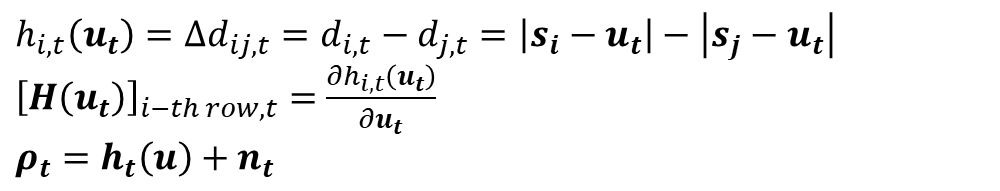

The ML estimate (for all of the 4 tags) is:

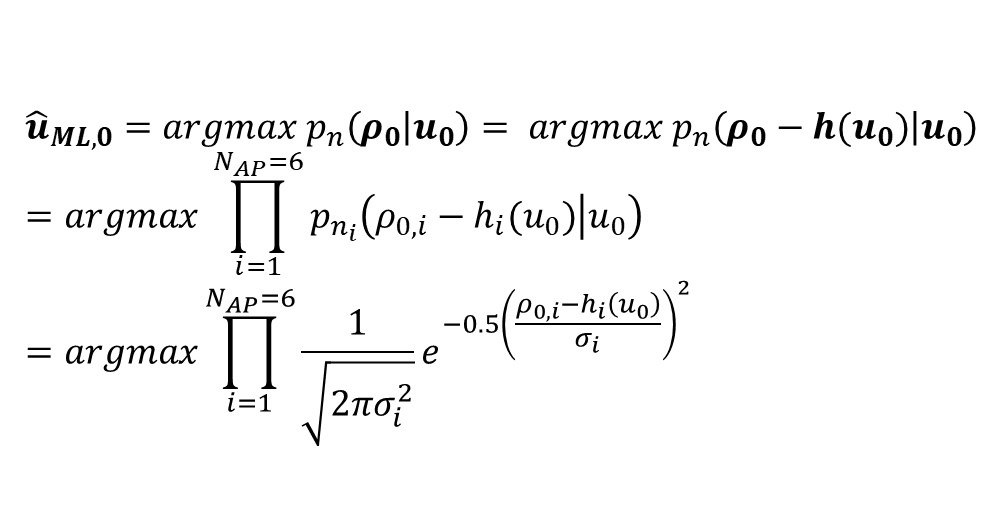

***[Showing the plots:]***

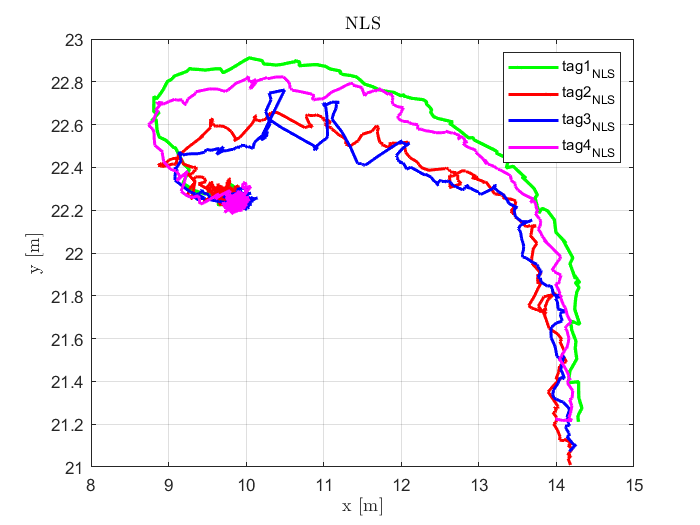

%% 2.2 Compute the likelihood of the measurement and evaluate the tags' estimated initial positions
u1_Init=maxLikelihood(parameters, rho1 , AP , x , y , show_plots_ML);
% pause
% close all;
u2_Init=maxLikelihood(parameters, rho2 , AP , x , y , show_plots_ML);
% pause
% close all;
u3_Init=maxLikelihood(parameters, rho3 , AP , x , y , show_plots_ML);
% pause
% close all;
u4_Init=maxLikelihood(parameters, rho4 , AP , x , y , show_plots_ML);
else
    % I set all 4 to the same initial position for coherence
    u_Init = [ (parameters.xmax-parameters.xmin).*rand(1,1) + parameters.xmin , (parameters.ymax-parameters.ymin).*rand(1,1) + parameters.ymin ];
    u1_Init = u_Init;
    u2_Init = u_Init;
    u3_Init = u_Init;
    u4_Init = u_Init;
    
end

From the initial estimations computed I observed we could have also used a point roughly in the middle of the scenario.


%% 3. Iterative NLS
if NLS==1
parameters.NiterMax = NLS_iterations;
parameters.iterative_step = NLS_iterative_step;


% Estimated trajectory vector in time per tag i:
[uHat1 , numberOfPerformedIterations1]=trackerNLS(parameters, AP, rho1, u1_Init , threshold_stopping_criterion);

[uHat2 , numberOfPerformedIterations2]=trackerNLS(parameters, AP, rho2, u2_Init , threshold_stopping_criterion);

[uHat3 , numberOfPerformedIterations3]=trackerNLS(parameters, AP, rho3, u3_Init , threshold_stopping_criterion);

[uHat4 , numberOfPerformedIterations4]=trackerNLS(parameters, AP, rho4, u4_Init , threshold_stopping_criterion);


**Iterative NLS:**

For the "snapshot localization" I've implemented the iterative NLS algorithm for every timestep $t$:

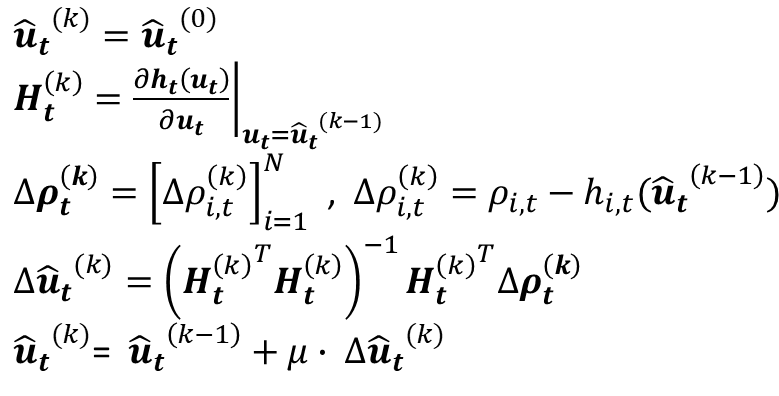

where you can set the iteration step $\mu$ in the Benchmark ("NLS Iterative step size") and also the maximum number of iterations ("NLS Number of iterations")

*Notice that for smaller *$\mu$* you may require a higher number of iterations.*

***Showing the plots:***

(if CRB is active it will plot the NLS and on top the ellipses)

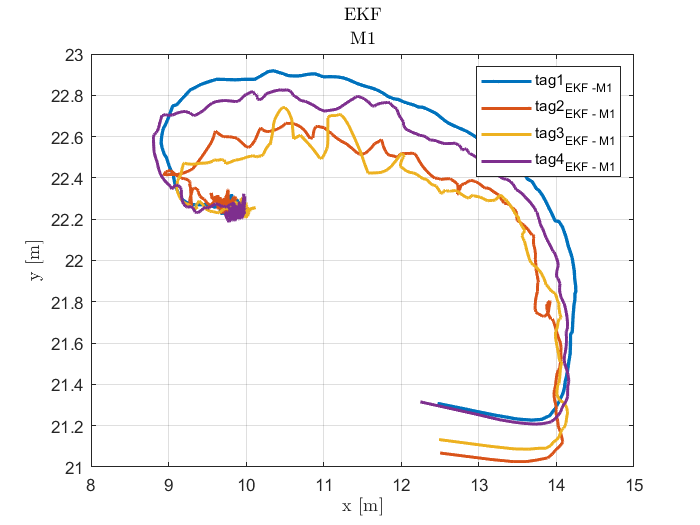

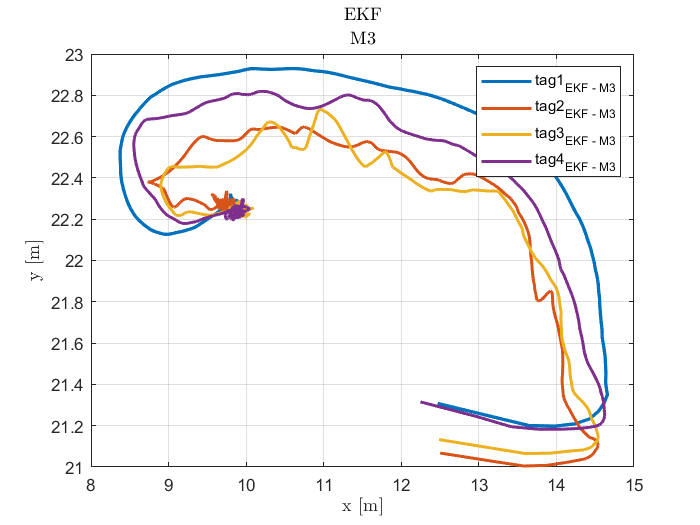

% plotting all together
figure;
%hold on;
plot(uHat1(:,1) , uHat1(:,2), '-g'); hold on;
plot(uHat2(:,1) , uHat2(:,2), '-r'); hold on;
plot(uHat3(:,1) , uHat3(:,2), '-b'); hold on;
plot(uHat4(:,1) , uHat4(:,2), '-m'); hold on;
legend('tag1_{NLS}','tag2_{NLS}','tag3_{NLS}','tag4_{NLS}')
xlabel('x [m]') , ylabel('y [m]');
title('NLS')
grid on;
end


if CRB==1
%% 4. Lower bound CRB for the covariance of the estimate (Really slow and the variance is very big wrt the final trajectory)
sigma=repmat(parameters.sigmaTDOA .^2,5,1);
R=diag(sigma);

**CRB:**

In this section the lower Cramer Rao Bound is computed on the previous estimates with NLS.

*The estimated trajectories have been sampled due to computational time required. (you can adjust the sampling setting in the Benchmark).*

***Showing the plots:***

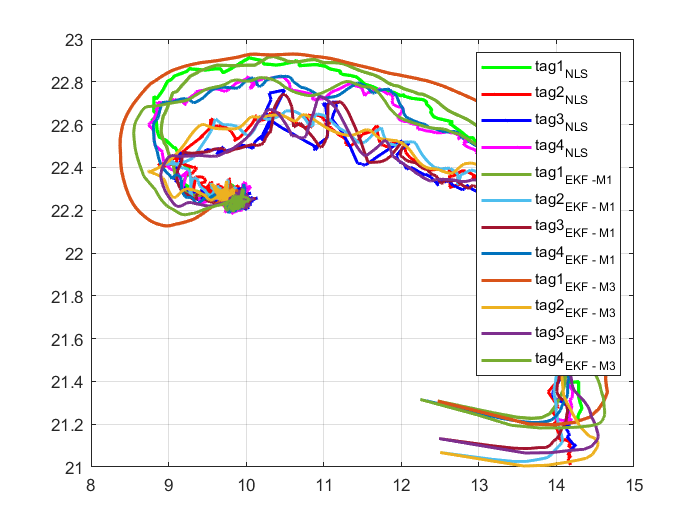

hold on;
set(gcf,'Visible','on')
uHat1_sampled=uHat1(1:num_samples:end,:);
for t=1:size(rho1,2)/num_samples
H = buildJacobianMatrixH(parameters , uHat1_sampled(t,:) , AP);
calculateEllipse( parameters , H , R , uHat1_sampled(t,:) , AP , TYPE , 3 , 1 , 'green');
end

uHat2_sampled=uHat2(1:num_samples:end,:);
for t=1:size(rho2,2)/num_samples
H = buildJacobianMatrixH(parameters , uHat2_sampled(t,:) , AP);
calculateEllipse( parameters , H , R , uHat2_sampled(t,:) , AP , TYPE , 3 , 2 , 'red');
end
% 

uHat3_sampled=uHat3(1:num_samples:end,:);
for t=1:size(rho3,2)/num_samples
H = buildJacobianMatrixH(parameters , uHat3_sampled(t,:) , AP);
calculateEllipse( parameters , H , R , uHat3_sampled(t,:) , AP , TYPE , 3 , 3 , 'blue');
end

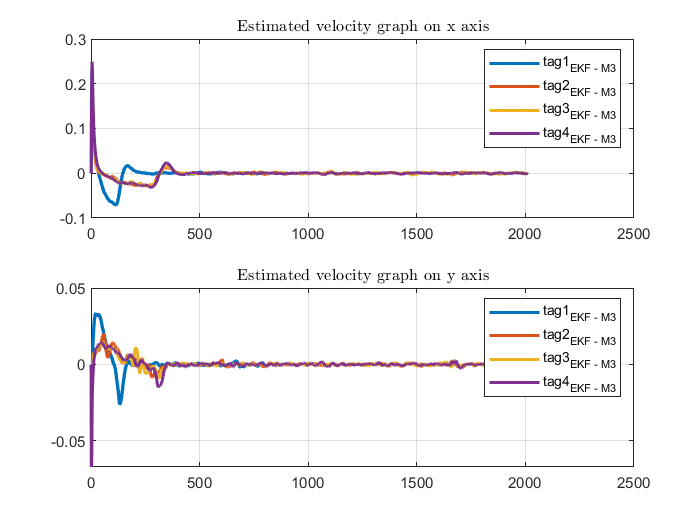


uHat4_sampled=uHat4(1:num_samples:end,:);
for t=1:size(rho4,2)/num_samples
H = buildJacobianMatrixH(parameters , uHat4_sampled(t,:) , AP);
calculateEllipse( parameters , H , R , uHat4_sampled(t,:) , AP , TYPE , 3 , 4 , 'magenta');
end
end

#### ***3) Track the AGV by KF/EKF***

**EKF:**

Since the measurement model is not linear I've select the Extend Kalman Filter method.

For comparisons purposes I've implemented EKF with both motion models M1 (random walk) and M3 (nearly-constant-velocity) as follows:

**Case 1)** 

**Motion model M1:**

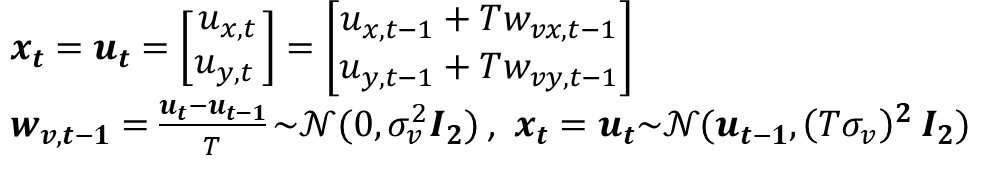

**Case 2)**

**Motion model M3:**

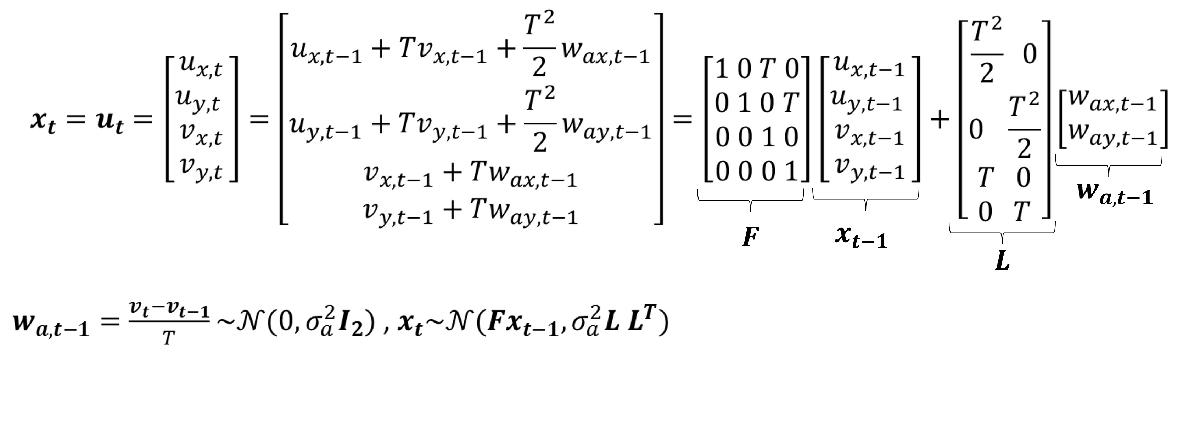

and then the rest is the same for both cases:

**Measurement model:**

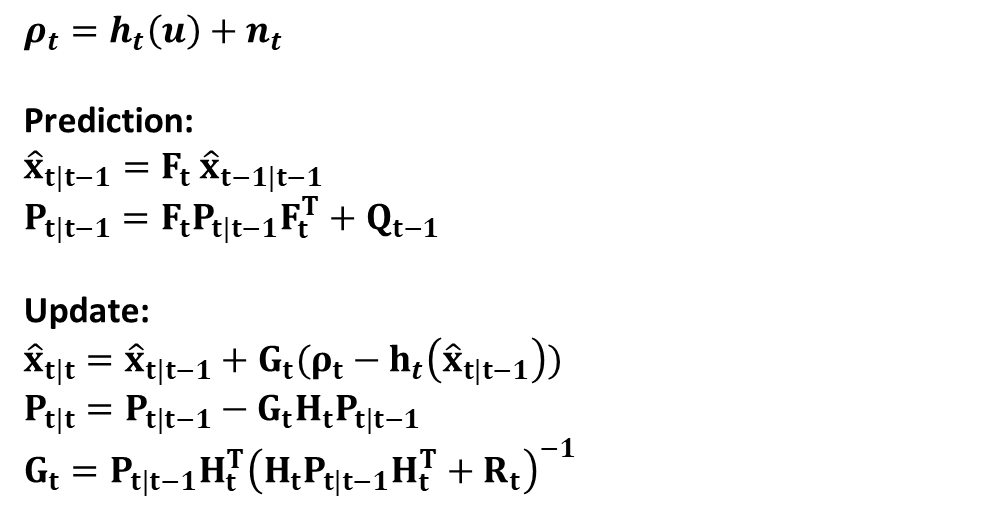

%% 1. Tracking with EKF (Non-linear measurement model)
if EKF==1

%% 1.1. Motion Model M1 (random-walk): Measurement of: position, State: position
MODEL='M1';


% Estimated trajectory vector in time per tag i:
xHat1=trackerEKF(parameters, AP , rho1, u1_Init , driving_noise_sigma_pos , sigma_driving_noise , MODEL , UE_init_COV_pos , UE_init_COV_vel , show_plots_covarianceEKFM1 , show_plots_covarianceEKFM3);

xHat2=trackerEKF(parameters, AP , rho2, u2_Init , driving_noise_sigma_pos , sigma_driving_noise , MODEL , UE_init_COV_pos , UE_init_COV_vel , show_plots_covarianceEKFM1 , show_plots_covarianceEKFM3);

xHat3=trackerEKF(parameters, AP , rho3, u3_Init , driving_noise_sigma_pos , sigma_driving_noise , MODEL , UE_init_COV_pos , UE_init_COV_vel , show_plots_covarianceEKFM1 , show_plots_covarianceEKFM3);

xHat4=trackerEKF(parameters, AP , rho4, u4_Init , driving_noise_sigma_pos , sigma_driving_noise , MODEL , UE_init_COV_pos , UE_init_COV_vel , show_plots_covarianceEKFM1 , show_plots_covarianceEKFM3);

***Showing the plots:***

% plotting all together
figure; 
plot(xHat1(:,1) , xHat1(:,2), 'MarkerFaceColor',[0.0510    0.5608    0.0745]); hold on;
plot(xHat2(:,1) , xHat2(:,2), 'MarkerFaceColor',[0.6353    0.0784    0.1843]); hold on;
plot(xHat3(:,1) , xHat3(:,2), 'MarkerFaceColor',[0.3020    0.7451    0.9333]); hold on;
plot(xHat4(:,1) , xHat4(:,2), 'MarkerFaceColor',[0.7176    0.2745    1.0000]); hold on;
legend('tag1_{EKF -M1}','tag2_{EKF - M1}','tag3_{EKF - M1}','tag4_{EKF - M1}')
xlabel('x [m]') , ylabel('y [m]'); grid on;
title('EKF',num2str(MODEL))  
hold off;

%% 1.2. Motion Model M3 (NCV -random force): Measurement of: position, State: position, velocity
MODEL='M3';

parameters.samplingTime = 1; 

% Estimated trajectory vector in time per tag i:
xHat1_m3=trackerEKF(parameters, AP , rho1, u1_Init , driving_noise_sigma_pos , sigma_driving_noise , MODEL , UE_init_COV_pos , UE_init_COV_vel , show_plots_covarianceEKFM1 , show_plots_covarianceEKFM3);

xHat2_m3=trackerEKF(parameters, AP , rho2, u2_Init , driving_noise_sigma_pos , sigma_driving_noise , MODEL , UE_init_COV_pos , UE_init_COV_vel , show_plots_covarianceEKFM1 , show_plots_covarianceEKFM3);

xHat3_m3=trackerEKF(parameters, AP , rho3, u3_Init , driving_noise_sigma_pos , sigma_driving_noise , MODEL , UE_init_COV_pos , UE_init_COV_vel , show_plots_covarianceEKFM1 , show_plots_covarianceEKFM3);

xHat4_m3=trackerEKF(parameters, AP , rho4, u4_Init , driving_noise_sigma_pos , sigma_driving_noise , MODEL , UE_init_COV_pos , UE_init_COV_vel , show_plots_covarianceEKFM1 , show_plots_covarianceEKFM3);

% plotting all together
figure; 
plot(xHat1_m3(:,1) , xHat1_m3(:,2), 'MarkerFaceColor',[0.6157    0.9686    0.2824]); hold on;
plot(xHat2_m3(:,1) , xHat2_m3(:,2), 'MarkerFaceColor',[1.0000    0.6510    0.1608]); hold on;
plot(xHat3_m3(:,1) , xHat3_m3(:,2), 'MarkerFaceColor',[0    0.3176    0.5294]); hold on;
plot(xHat4_m3(:,1) , xHat4_m3(:,2), 'MarkerFaceColor',[0.4941    0.1843    0.5569]); hold on;
legend('tag1_{EKF - M3}','tag2_{EKF - M3}','tag3_{EKF - M3}','tag4_{EKF - M3}')
xlabel('x [m]') , ylabel('y [m]'); grid on;
title('EKF',num2str(MODEL))  
end


**NLS vs. EKF-M1 vs. EKF-M3:**

Comparison between all the methods considered

***Showing the plots:***


%% 1.3. COMPARE THE DIFFERENCES
if show_plots_comparisonNLSvsEKF==1
figure; 

plot(uHat1(:,1) , uHat1(:,2), '-g'); hold on;
plot(uHat2(:,1) , uHat2(:,2), '-r'); hold on;
plot(uHat3(:,1) , uHat3(:,2), '-b'); hold on;
plot(uHat4(:,1) , uHat4(:,2), '-m'); hold on;

plot(xHat1(:,1) , xHat1(:,2), 'MarkerFaceColor',[0.05400    0.5708    0.0845]); hold on;
plot(xHat2(:,1) , xHat2(:,2), 'MarkerFaceColor',[0.6353    0.0784    0.1843]); hold on;
plot(xHat3(:,1) , xHat3(:,2), 'MarkerFaceColor',[0.3020    0.7451    0.9333]); hold on;
plot(xHat4(:,1) , xHat4(:,2), 'MarkerFaceColor',[0.7176    0.2745    1.0000]); hold on;

plot(xHat1_m3(:,1) , xHat1_m3(:,2), 'MarkerFaceColor',[0.6157    0.9686    0.2824]); hold on;
plot(xHat2_m3(:,1) , xHat2_m3(:,2), 'MarkerFaceColor',[1.0000    0.6510    0.1608]); hold on;
plot(xHat3_m3(:,1) , xHat3_m3(:,2), 'MarkerFaceColor',[0    0.3176    0.5294]); hold on;
plot(xHat4_m3(:,1) , xHat4_m3(:,2), 'MarkerFaceColor',[0.4000    0.1800    0.5500]); hold on;
grid on;
legend('tag1_{NLS}','tag2_{NLS}','tag3_{NLS}','tag4_{NLS}','tag1_{EKF -M1}','tag2_{EKF - M1}','tag3_{EKF - M1}','tag4_{EKF - M1}','tag1_{EKF - M3}','tag2_{EKF - M3}','tag3_{EKF - M3}','tag4_{EKF - M3}')
end

**Plotting of EKF- M3 estimated speeds:**

***Showing the plots:***

if show_plots_vel_EKF_M3==1
%% Plotting of EKF M3 estimated speeds
figure;
subplot(2,1,1);
plot(xHat1_m3(:,3) , 'MarkerFaceColor',[0.6157    0.9686    0.2824]); hold on;
plot(xHat2_m3(:,3) , 'MarkerFaceColor',[1.0000    0.6510    0.1608]); hold on;
plot(xHat3_m3(:,3) , 'MarkerFaceColor',[0    0.3176    0.5294]); hold on;
plot(xHat4_m3(:,3) , 'MarkerFaceColor',[0.4941    0.1843    0.5569]); hold on;

title ('Estimated velocity graph on x axis'); grid on;
legend('tag1_{EKF - M3}','tag2_{EKF - M3}','tag3_{EKF - M3}','tag4_{EKF - M3}')

subplot(2,1,2);
plot(xHat1_m3(:,4) ,  'MarkerFaceColor',[0.6157    0.9686    0.2824]); hold on;
plot(xHat2_m3(:,4) , 'MarkerFaceColor',[1.0000    0.6510    0.1608]); hold on;
plot(xHat3_m3(:,4) , 'MarkerFaceColor',[0    0.3176    0.5294]); hold on;
plot(xHat4_m3(:,4) , 'MarkerFaceColor',[0.4941    0.1843    0.5569]); hold on;

title ('Estimated velocity graph on y axis'); grid on;
legend('tag1_{EKF - M3}','tag2_{EKF - M3}','tag3_{EKF - M3}','tag4_{EKF - M3}')

end

#### EXTRAS

Plotting the trajectories estimated with EKF-M3 evolving wrt the timesteps. 



%% EXTRA (based on EKF-M3)

% Just to recreate the evolution in time (based on time-steps) of the
% trajectories. I really suggest to tune the value "speedup" in the
% Benchmark to speed up the plotting otherwise it's 1s=1time-step.
% For the tag1 (the faulty one) the plotting in time it's different from the others
% since the malfunction in time resulted in a wrong time-sampling of the
% tag1's measures. If you wish you can just skip the commented "save to
% gif parts".




if extra_show_pseudo_evolution_in_time==1
    
t = 1:1:parameters_rho4.rho_TimeSteps; %longenst time column
x1 = xHat1_m3(:,1); 
y1 = xHat1_m3(:,2); 
x2 = xHat2_m3(:,1); 
y2 = xHat2_m3(:,2); 
x3 = xHat3_m3(:,1); 
y3 = xHat3_m3(:,2); 
x4 = xHat4_m3(:,1); 
y4 = xHat4_m3(:,2); 
figure;
set(gcf,'Visible','on')
% % to save to gif [file name]
% filename = 'EKF-M3.gif';

hold on
p_1 = plot(x1(1),y1(1),'color',[0,1,0],'linewidth',2);
p_2 = plot(x2(1),y2(1),'color',[1,0,0],'linewidth',2);
p_3 = plot(x3(1),y3(1),'color',[0,0,1],'linewidth',2);
p_4 = plot(x4(1),y4(1),'color',[0.5,0,0.5],'linewidth',2);
legend('tag1_{EKF - M3}','tag2_{EKF - M3}','tag3_{EKF - M3}','tag4_{EKF - M3}')
grid on

for k = 2:length(x4-1)
    
    if k<parameters_rho1.rho_TimeSteps %It's the faulty tag
        set(p_1,'xdata',x1(1:k),'ydata',y1(1:k));
    end

    if k<parameters_rho2.rho_TimeSteps
        set(p_2,'xdata',x2(1:k),'ydata',y2(1:k)); hold on;
    end

    if k<parameters_rho3.rho_TimeSteps
        set(p_3,'xdata',x3(1:k),'ydata',y3(1:k)); hold on;
    end
    
    set(p_4,'xdata',x4(1:k),'ydata',y4(1:k)); hold on;
    title('Timer:', num2str(t(k),2))
    pause((t(k+1)-t(k))*speedup);
   
%     
%     % save to gif
%      frame = getframe(1);
%       im = frame2im(frame);
%       [imind,cm] = rgb2ind(im,256);
%       if k == 2
%           imwrite(imind,cm,filename,'gif', 'Loopcount',inf);
%       else
%           imwrite(imind,cm,filename,'gif','WriteMode','append');
%       end
end
end


